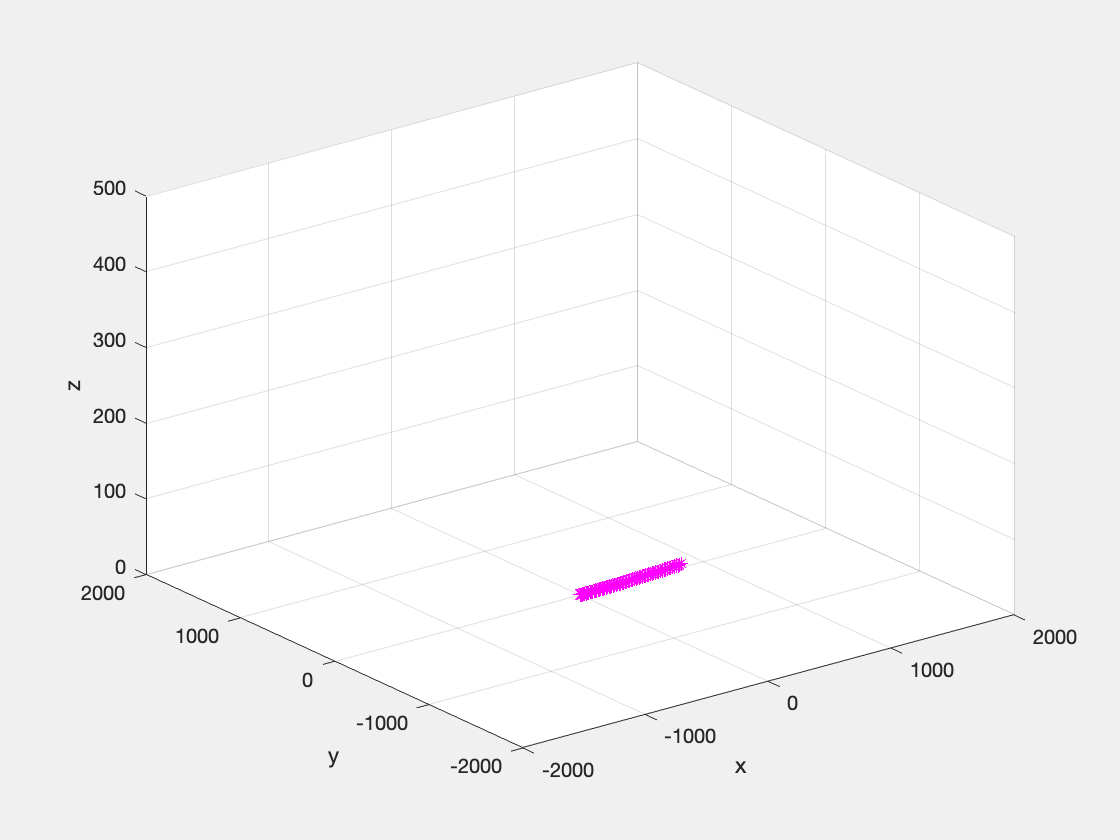

clear 
clf 


%y0 = [0,0,400,0];
%tspan = [0,20];
%[t,y] = ode45(@ODE,tspan,y0);

% Define constants
g = 9.81; % Acceleration due to gravity
m = 10; % Mass of the rocket
Fthrust = 10; % Thrust force of the rocket
Fdrag = 0.1; % Drag force on the rocket

% Define initial conditions
x0 = 0; % Initial x position
y0 = 0; % Initial y position
z0 = 0; % Initial z position
vx0 = 100; % Initial x velocity
vy0 = 0; % Initial y velocity
vz0 = 0; % Initial z velocity

% Define time range for simulation
t0 = 0; % Start time
tf = 20; % End time
dt = 0.1; % Time step
t = t0:dt:tf; % Time range for simulation

y0 = [x0, y0, z0, vx0, vy0, vz0]; % Initial conditions
[t,y] = ode45(@rocketDynamics,t,y0);

% Plot with animation 
for i=1:length(y)

plot3(y(i,1),y(i,2),y(i,3),'*m','LineWidth',0.1);
 axis([-2000 2000 -2000 2000 0 500])

xlabel('x');
ylabel('y');
zlabel('z');

 grid on;
 hold on;
 pause(0.1);
  
end



% Plot av derivatan, dvs hastigheten
hold off 
clf

plot(t,y(:,4), 'm', 'LineWidth', 2)
hold on 

grid on
xlabel("Sekunder")
ylabel("Hastighet")
title("Hastigheten över tid")

plot(t,y(:,5), 'black','LineWidth',2)
legend("Hastighet i X-led","Hastighet i Y-led")
legend('Location','southeast')

plot(t,y(:,6), 'blue','LineWidth',2)
legend("Hastighet i Z-led","Hastighet i Y-led")
legend('Location','southeast')

% Vinkel över tid

clf 
hold off

for i=1:length(t)
    
 plot(t,vinkel(t),'*m','LineWidth',1);
 
 grid on;
 hold on;
 pause(0.01);
 
 xlim([0,20])

 yticks([0 pi/2 pi 3*pi/2])
 yticklabels({'0','π/2','π','3π/2'})

 ylim([0 3*pi/2])

 xlabel("Sekunder")
 ylabel("Radianer")
 title("θ(t)")
  
end